*wersja 22.10.2025*

# Raport z ćwiczenia FRA

**Data: 17.04.2025**

**Imię i nazwisko: Marcin Wolder**

Sprawozdanie z ćwiczeń laboratoryjnych powinno składać się z TRZECH części : REZULTATY / ANALIZA I WNIOSKI / ODPOWIEDZI NA PYTANIA (chyba że instrukcja do ćwiczenia określa to inaczej).

## REZULTATY

Zanotuj określone w treści ćwiczenia parametry algorytmów, otrzymane rezultaty, itp. 

Opc. zamieść listę dodatkowych plików dołączonych do sprawozdania (dodatkowe pliki to np. fragmenty kodu, pliki danych otrzymane w trakcie ćwiczenia, itp.) 

**Uwaga - ten interaktywny skrypt jest zautomatyzowany, tzn. wystarczy uruchomić odpowiednie sekcje skryptu aby uzupełnić sprawozdanie (rezultaty).**

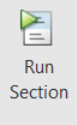

W przyszłych ćwiczeniach zachęcam do tworzenia własnych interaktywnych skryptów, automatyzujących tworzenie sprawozdania. 

**Taki skrypt można szybko skonwertować do pliku PDF (sprawozdania na UPEL oddajemy w formacie PDF)**

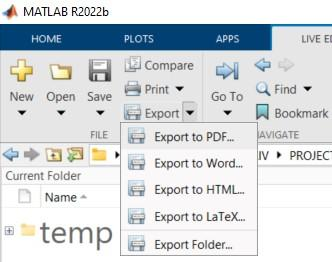

Są dostępne różne tryby zamieszczania rezultatów obliczeń w skrypcie - do ćwiczenia wykorzystujemy "outpul inline", czyli rezultaty wkomponowane w treść skryptu.

Można to zmienić klikając w odpowiednie ikonki z prawej strony edytora:

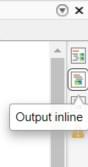

### Wskazówki

W katalogu solutions/ są umieszczone rozwiązania, ale proszę z nich nie korzystać tylko pomyśleć najpierw przez chwilę. 

### Część Ia

Utwórz skrypt `przyklad_etap2.m `i uruchom go wg instrukcji podanej w lekcji UPEL.  

Uruchom tą sekcję aby uzupełnić sprawozdanie - rezultaty wykonania skryptu `przyklad_etap2.m`

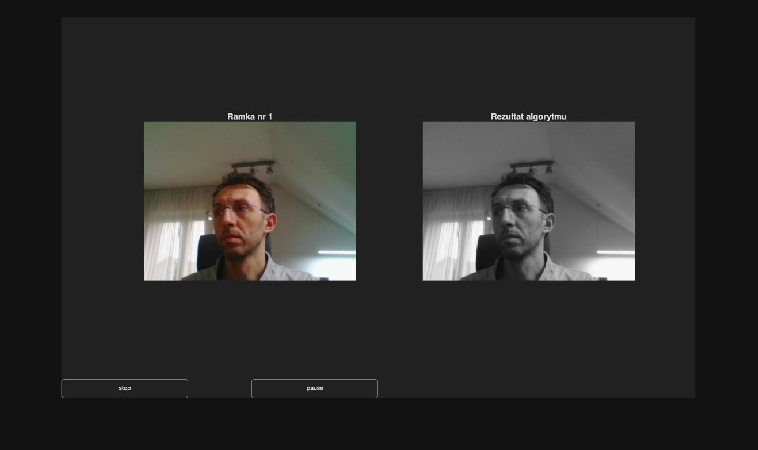

im = imread('przyklad_etap2_printscreen.jpg');
imshow(im,[])

### Część Ib

Sprawdź działanie klasy `exportPrzyklad.m` – uruchom linia po linii przykład zawarty na początku, w opisie klasy.

Uruchom tą sekcję aby uzupełnić sprawozdanie.

T = readtable("test.txt")

T = 2×2 table
    NrRamki    Rezultat
    _______    ________

       1       0.81472 
       2       0.90579 


### Część Ic

Uruchom (utworzony wcześniej wg instrukcji) skrypt `przyklad_etap3.m` dostosowując odpowiednią nazwę pliku wyjściowego w sekcji: opisanej "Zrzut ekranu - zapis do pliku". 

Nazwa pliku powinna zostać zmieniona na: "przyklad_etap3_printscreen.jpg"

Uruchom tą sekcję aby uzupełnić sprawozdanie - rezultaty wykonania skryptu `przyklad_etap3.m`

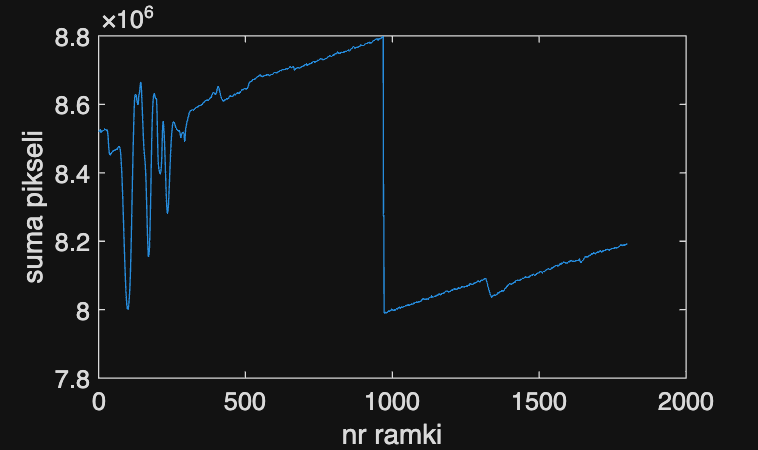

T = readtable("test3.txt");
if isempty(T)
    warning('Nie wyeksportowano żadnych danych w skrypcie "przyklad_etap3.m" ')
end
plot(T.NrRamki,T.Rezultat)
xlabel('nr ramki')
ylabel('suma pikseli')

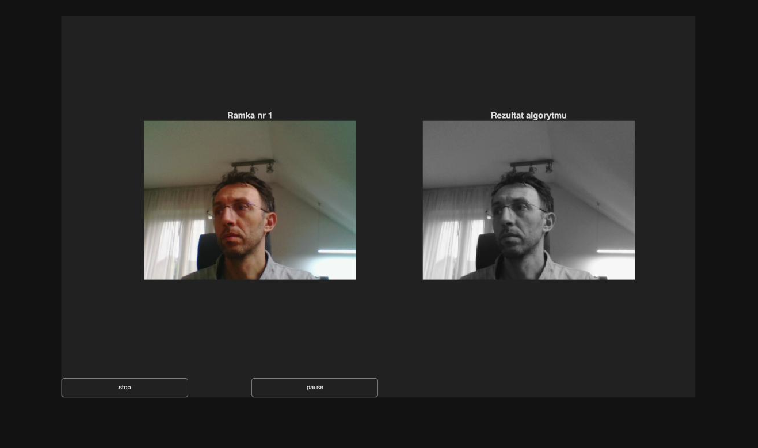


if exist('exportObj','var')
    warning('Nie usunięto obiektu "exportObj" w skrypcie "przyklad_etap3.m" ')
end
im = imread('przyklad_etap3_printscreen.jpg');
imshow(im,[])

### Część 2a

Uruchom skrypt `testHarness_0.m`

Uruchom tą sekcję aby uzupełnić sprawozdanie - rezultaty wykonania skryptu `testHarness_0.m`

T = readtable("out.txt","Delimiter","=")

T = 1799×2 table
        Var1        Var2
    ____________    ____

    {'Ramka nr'}      1 
    {'Ramka nr'}      2 
    {'Ramka nr'}      3 
    {'Ramka nr'}      4 
    {'Ramka nr'}      5 
    {'Ramka nr'}      6 
    {'Ramka nr'}      7 
    {'Ramka nr'}      8 
    {'Ramka nr'}      9 
    {'Ramka nr'}     10 
    {'Ramka nr'}     11 
    {'Ramka nr'}     12 
    {'Ramka nr'}     13 
    {'Ramka nr'}     14 
    {'Ramka nr'}     15 
    {'Ramka nr'}     16 


if isempty(T)
    warning('Nie wyeksportowano żadnych danych w skrypcie "testHarness_0.m" ')
end

### Część 2b

Sprawdź działanie klasy **myDataSourceVid**`.m` – uruchom linia po linii przykład zawarty na początku, w opisie klasy.

Uruchom tą sekcję aby uzupełnić sprawozdanie.

if ~exist('vidFPS','var')|~exist('nFrames','var')|~exist('imSize','var')
    warning('Prawdopodobnie nie uruchomiono przykładu użycia - brak zmiennej vidFPS lub nFrames lub imSize')
else
    disp(['liczba ramek  = ' num2str(nFrames)])
    disp(['FPS           = ' num2str(vidFPS)])
    disp(['rozdzielczość = ' num2str(imSize)])
end

liczba ramek  = Inf


FPS           = Inf


rozdzielczość = 1080  1920


### Zadanie 3a

Uzupełnij klasę **myDataSourceCam **wg instrukcji do ćwiczenia i przetestuj jej działanie. Pamiętaj o ustawieniu odpowiedniego numeru kamery.

Uruchom tą sekcję aby uzupełnić sprawozdanie.

Poprawne uzupełnienie klasy nie powinno skutkować błędami i ostrzeżeniami poniżej (za to powinien zostać wyświetlony obraz). *Jeśli tak się nie dzieje zamieść odpowiednią informację w sprawozdaniu wraz z własną próbą odkrycia przyczyny problemu.*

try
     parametryImportu        = [];
     parametryImportu.nr     = 1; 
     vid1                    = myDataSourceCam(parametryImportu);    
catch Me    
    disp('Źle zainicjalizowany obiekt kamery - możliwe przyczyny: ')
    disp(' - w zmiennej "obj.vidObj" powinien być obiekt webcam')
    disp(' - numer kamery powinien być większy od zera, i nie większy niż liczba dostępnych kamer ')
    disp(' - lista kamer: ')
    webcamlist    
    error(Me.message)            
end

obj =   myDataSourceCam with properties:

     vidFPS: Inf
    nFrames: Inf
     imSize: [1080 1920]
       test: 0


---=== myDataSourceCam ===---
Dane źródła video:       
> numer kamery    = 1
> liczba ramek    = Inf
> FPS             = Inf
> rozdzielczość   = 1080x1920


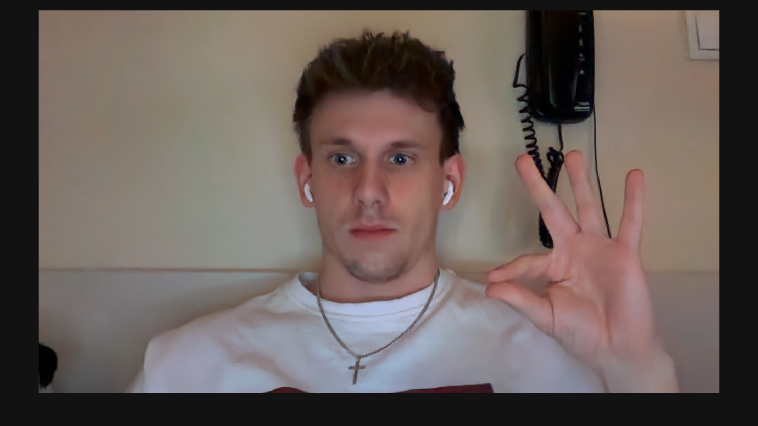

try
     IM      = vid1.pobierzDane;
     vidFPS  = vid1.vidFPS;
     nFrames = vid1.nFrames;
     imSize  = vid1.imSize;    
     imshow(IM)
catch Me    
    disp('Źle uzupełniony kod metody "pobierzDane" - możliwe przyczyny: ')
    disp(' - metoda nie zwraca obrazu w zmiennej "dataFrame" ')
    error(Me.message)            
end

imSize2     = size(IM);
assert(all(imSize2(1:2)==imSize),"Źle uzupełniony kod metody 'pobierzDane' - rozmiar obrazu nie zgadza się z ustawieniami kamery.")
disp(vid1.test)

     0



clear vid1   

### Zadanie 3b

Uzupełnij klasę **myExportDataVid **wg instrukcji do ćwiczenia.

Uruchom tą sekcję aby uzupełnić sprawozdanie.

Poprawne uzupełnienie klasy nie powinno skutkować błędami i ostrzeżeniami poniżej (za to powinien zostać wyświetlony obraz). *Jeśli tak się nie dzieje zamieść odpowiednią informację w sprawozdaniu wraz z własną próbą odkrycia przyczyny problemu.*

warning off
delete myexport.txt
delete myexport.avi
warning on
RGB                          = imread('ngc6543a.jpg');
parametryEksportu            = [];
parametryEksportu.nazwapliku = 'myexport.avi';
exportObj                    = myExportDataVid(parametryEksportu);    

---=== myExportDataVid ===---
Nazwa pliku wyjściowego AVI  =       myexport.avi
Nazwa pliku wyjściowego TXT  =       myexport.txt



dane_do_eksportu             = [];
dane_do_eksportu.iter        = 1; 
dane_do_eksportu.outVidData  = RGB;
exportObj.eksportujDane(dane_do_eksportu);
disp(exportObj.test)

     0



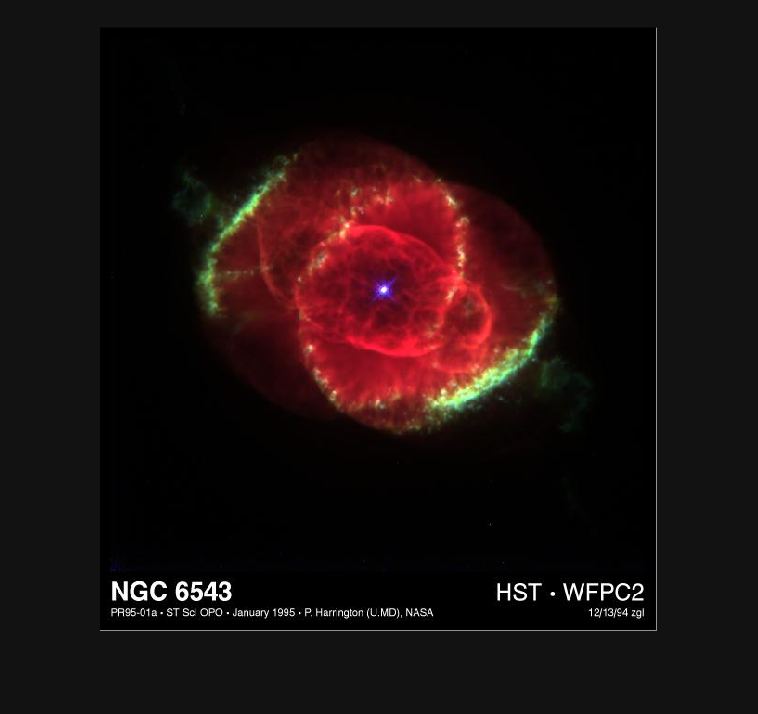

vidtestobj = exportObj.vidObj;
delete(exportObj)  
try
    writeVideo(vidtestobj, RGB);
    warning("myExportDataVid nie został uzupełniony poprawnie :")
    warning(" -  prawdopodobnie nie zamknięto pliku video w metodzie 'delete'")    
catch Me
end
if ~exist(parametryEksportu.nazwapliku,"file")
    warning("myExportDataVid nie został uzupełniony poprawnie - brak pliku wyjściowego video")
end
try
    vidtest = VideoReader(parametryEksportu.nazwapliku);
    im      = vidtest.readFrame;
    imshow(im)
catch Me
    warning("myExportDataVid nie został uzupełniony poprawnie :")
    warning(" - prawdopodobnie nie zapisano żadnej ramki do pliku video")
    disp(Me)
end

clear vidtest


### Zadanie 3c

Uzupełnij kod w skrypcie **testHarness_1.m **wg instrukcji do ćwiczenia.

Uruchom tą sekcję aby uzupełnić sprawozdanie.

Poprawne uzupełnienie kodu nie powinno skutkować błędami i ostrzeżeniami poniżej (za to powinien zostać wyświetlony obraz).

testHarness_1

obj =   myDataSourceCam with properties:

     vidFPS: []
    nFrames: []
     imSize: []
       test: 0


---=== myDataSourceCam ===---
Dane źródła video:       
> numer kamery    = 1
> liczba ramek    = Inf
> FPS             = Inf
> rozdzielczość   = 1080x1920
---=== myAlgorithmTemplate ===---
---=== myExportDataVid ===---
    "Nazwa pliku wyjściowego AVI  =       "    "test_harness.avi"

    "Nazwa pliku wyjściowego TXT  =       "    "test_harness.txt"

---=== myVisualization0 ===---
Początek przetwarzania
Zakończenie przetwarzania - obiekty usunięte


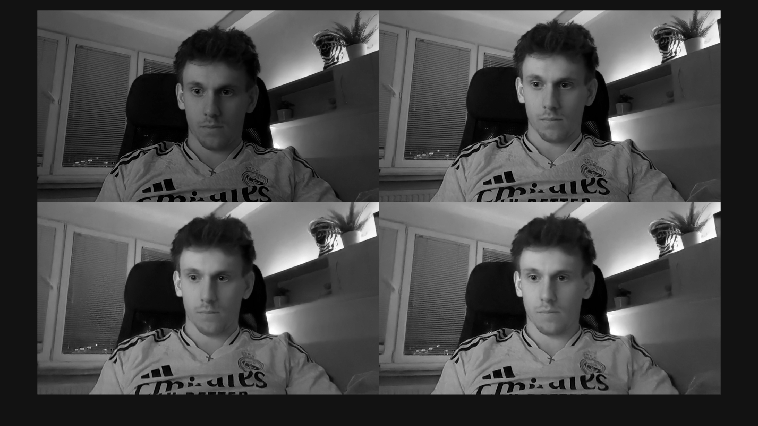

if exist(parametryEksportu.nazwapliku,"file")
    vidtest = VideoReader(parametryEksportu.nazwapliku);
    imtab = [];
    for i=1:4
        imtab(:,:,:,i)      = vidtest.readFrame;
    end
    clear vidtest
    montage(imtab/255)
end

T = readtable(strrep(parametryEksportu.nazwapliku,'.avi','.txt'),"Delimiter",",")

T = 51×2 table
    iter    timestamp
    ____    _________

      1      851.19  
      2      1303.2  
      3      1459.7  
      4      1632.2  
      5        1833  
      6      1907.9  
      7      1992.6  
      8      2063.4  
      9      2131.9  
     10      2199.8  
     11      2316.4  
     12      2431.2  
     13      2509.9  
     14      2585.6  
     15      2665.7  
     16      2728.9  


if isempty(T)
    warning('Nie wyeksportowano żadnych danych w skrypcie "testHarness_1.m" ')
end
disp(parametryEksportu.nazwapliku)

test_harness.avi


### Zadanie 3d

Uzupełnij poniższy kod i uruchom tą sekcję:

T = readtable(strrep(parametryEksportu.nazwapliku,'.avi','.txt'),"Delimiter",",");

ts    = T.timestamp;   % wybór z tabeli T kolumny zwierającej timestamp
dts = diff(ts);        % wyznaczenie różnicy czasu między ramkami (pomoc -> doc diff)
FPS=median(dts)     % wyznaczenie FPS (użycie f. median na wektorze różnic czasu)

FPS = 84.7035

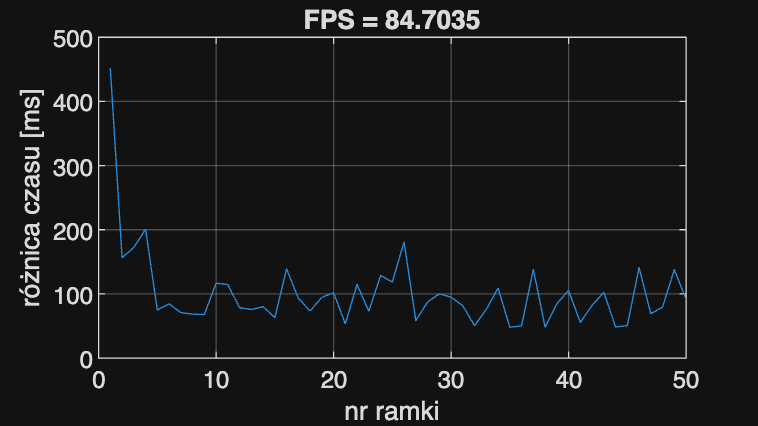


plot(dts)              % wyświetlenie różnic czasu pomiędzy ramkami
grid on
xlabel('nr ramki')
ylabel('różnica czasu [ms]')
title(['FPS = ' num2str(FPS)])

Czy akwizycja danych jest stabilna (czas akwizycji ramek jest podobny)? 

## ANALIZA i WNIOSKI

W tym ćwiczeniu jako sprawozdanie oddajemy wygenerowany z tego skryptu plik PDF z rezultatami. Upewnij się, że w wygenerowanym pliku PDF są wszystkie rezultaty z poprzednich sekcji skryptu oraz odpowiedzi na pytania poniżej.

## ODPOWIEDZI NA PYTANIA

1) Wymień i krótko uzasadnij 3 elementy ćwiczenia, które zwróciły Twoją uwagę lub są Twoim zdaniem ważne.

- Automatyzacja tworzenia sprawozdań. Skrypty interaktywne typu Live Script przyspieszają dokumentację, np. opcja "Export to PDF" od razu generuje dokument z wynikami obliczeń.

- Obiektowe zarządzanie źródłami obrazu. Ułatwia to skalowanie kodu, np. zaimplementowana klasa `myDataSourceCam `dziedziczy wspólny interfejs i pozwala na bezproblemową zmianę pobierania obrazu z pliku wideo na kamerę.

- Obliczanie rzeczywistego klatkażu (FPS). Wykorzystanie mediany do różnic czasu eliminuje wpływ pojedynczych opóźnień systemu, np. użycie funkcji `median(dts)` na wektorze różnic czasowych daje wiarygodny wynik FPS.

2) Wymień i krótko uzasadnij 2 rzeczy z ćwiczenia, które były dla Ciebie trudne. Przykładowo - w przypadku gdy potrzebna była podpowiedź (skrypt "solution") opisz krótko co było dla Ciebie niezrozumiałe w zadaniu i dlaczego  potrzebowałeś/potrzebowałaś podpowiedzi.

- Odpowiednie zwalnianie zasobów. Brak destrukcji obiektów blokuje dostęp do plików, np. niepoprawne zamknięcie obiektu wideo w metodzie `delete` klasy `myExportDataVid` skutkuje błędami odczytu.

- Obsługa błędów sprzętowych. Inicjalizacja klas wymaga rygorystycznej walidacji, np. obsługa wyjątków w momencie, gdy podany numer kamery przekracza liczbę dostępnych urządzeń lub obiekt `vidObj` jest pusty

3) Zadaj 1 pytanie związane z tym ćwiczeniem (np. co jest dla Ciebie niezrozumiałe lub co chciałbyś/chciałabyś się jeszcze dowiedzieć).

- W jaki sposób asynchroniczne pobieranie klatek wpłynęłoby na redukcję opóźnień i stabilizację klatkażu względem obecnego, sekwencyjnego podejścia? Przykładowo, czy rozdzielenie akwizycji obrazu i zapisu na dysk do osobnych wątków w środowisku MATLAB wyeliminowałoby wahania czasu między klatkami sięgające 150 ms, które widać na wykresie różnicy czasu?